syms x(t)

dx = diff(x,1)

$$dx(t) = \frac{\partial }{\partial t}x\left(t\right)$$

ddx = diff(x,2)

$$ddx(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)$$

eq1a = dx + 3*x ==0

$$eq1a(t) = \frac{\partial }{\partial t}x\left(t\right)+3\,x\left(t\right)=0$$

cond1a = x(0)==1

$$cond1a = x\left(0\right)=1$$

ans1a = dsolve(eq1a, cond1a)

$$ans1a = {\mathrm{e}}^{-3\,t}$$

eq1b = ddx + x == 0

$$eq1b(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+x\left(t\right)=0$$

cond1b = [x(0)==1,dx(0)==0]

$$cond1b = \left(\begin{array}{cc} x\left(0\right)=1 & \left({\left(\frac{\partial }{\partial t}x\left(t\right)\right)|}_{t=0}\right)=0 \end{array}\right)$$

ans1b = dsolve(eq1b, cond1b)

$$ans1b = \cos\left(t\right)$$

% 問題 2.
% 図と一致するまでKとTを調節すること

s = tf('s') % s は tf (transfer function)クラスのオブジェクト

s =
 
  s
 
連続時間の伝達関数です。
モデル プロパティ


K = 1

K = 1

T = 1

T = 1

G = K/(T*s+1)

G =
 
    1
  -----
  s + 1
 
連続時間の伝達関数です。
モデル プロパティ


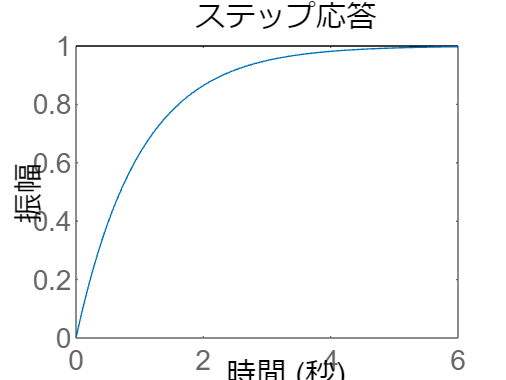


step(G)

% 問題 3.
syms s % s は sym (symbolic math)クラスのオブジェクト
G = 1/(s+1)/(s+2)

$$G = \frac{1}{\left(s+1\right)\,\left(s+2\right)}$$

ilaplace(1/s*G)

$$ans = \frac{{\mathrm{e}}^{-2\,t}}{2}-{\mathrm{e}}^{-t}+\frac{1}{2}$$